G =
 
         50000
  --------------------
  s^3 + 60 s^2 + 500 s
 
Continuous-time transfer function.
Model Properties


% Step 1: Define the transfer function G(s)
clf;
s = tf('s');
G = 50000/(s*(s + 10)*(s + 50))

G =
 
         50000
  --------------------
  s^3 + 60 s^2 + 500 s
 
Continuous-time transfer function.
Model Properties


G = tf([1],[1 1])

G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


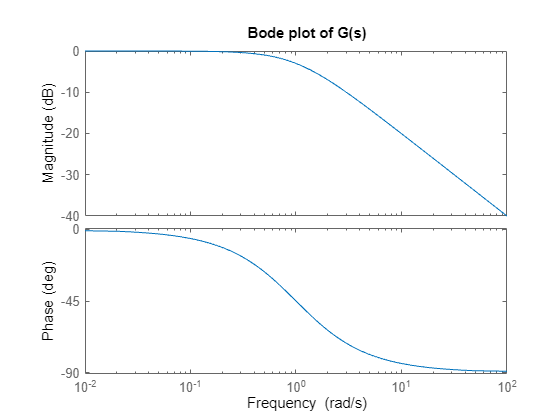

bode(G)
title('Bode plot of G(s)')


saveas(gcf, fullfile("A4_imgs/q1_bode_nothing.png"));

Error using saveas
Invalid or missing path: A4_imgs\q1_bode_nothing.png

% Redesign the lead compensator
PM = 50

PM = 50

Wcg_desired = 20; % Desired gain crossover frequency in rad/sec
[mag, phase] = bode(G, Wcg_desired)

mag = 2.0761

phase = -175.2364

phi = PM - (180 + phase); % Additional phase lead required
phi = phi * pi/180; % Convert to radians
beta = (1 - sin(phi))/(1 + sin(phi)) % Calculate beta

beta = 0.1696

T = 1/(Wcg_desired * sqrt(beta)) % Calculate time constant T

T = 0.1214

% beta = 0.17
% T = 0.12

% Add the redesigned compensator to the system
C_new = (s + 1/T) / (s + 1/(beta * T)); % Redesigned lead compensator transfer function
Gc_new = C_new * G; % System with redesigned compensator    

% Analyze the Bode plot again
figure
[mag, phase] = bode(Gc_new, 20)

mag = 0.8550

phase = -130

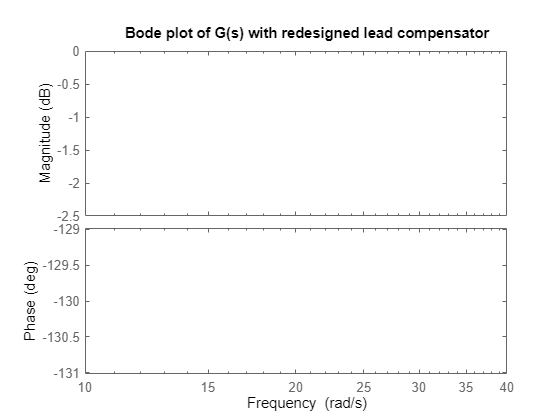

bode(Gc_new, 20)
title('Bode plot of G(s) with redesigned lead compensator')


[Gm_new, Pm_new, Wcp_new, Wcg_new] = margin(Gc_new)

Gm_new = 5.1531

Pm_new = 55.3590

Wcp_new = 50.9598

Wcg_new = 17.5350

clear

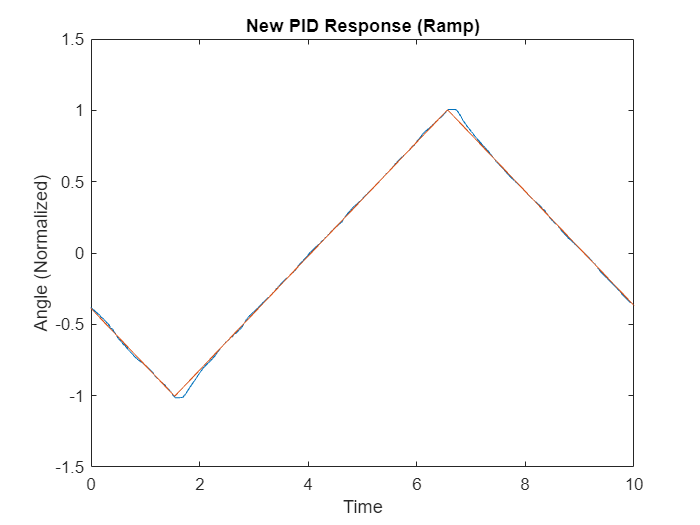

plot(linspace(0,10,1000),data_422_kp_4_kd_0p09_ki_25_ramp_long_Value)
title('New PID Response (Ramp)')
xlabel('Time') 
ylabel('Angle (Normalized)') 

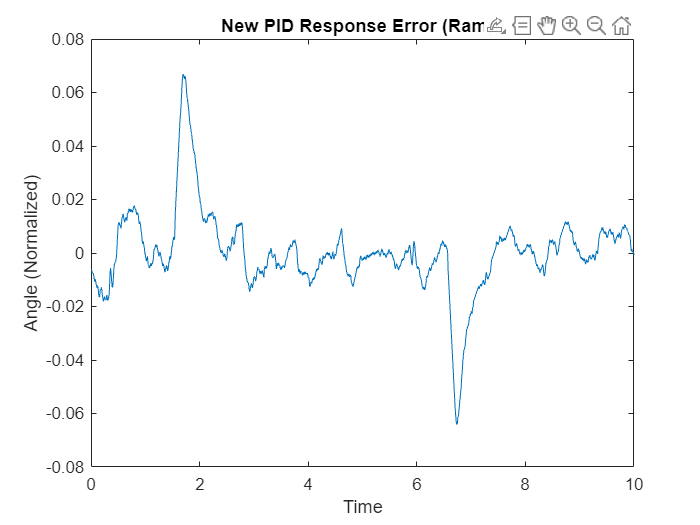

plot(linspace(0,10,1000),data_422_kp_4_kd_0p09_ki_25_ramp_long_Value(:,2)-data_422_kp_4_kd_0p09_ki_25_ramp_long_Value(:,1))
title('New PID Response Error (Ramp)')
xlabel('Time') 
ylabel('Angle (Normalized)') 